clc;
clear all;

% Get the device information structure
info = audiodevinfo;

% Check if the 'input' field exists and has data
if isfield(info, 'input') && ~isempty(info.input)
    fprintf('Available Input Devices:\n');
    fprintf('---------------------------\n');

    % Loop through the input array directly
    for i = 1:length(info.input)
        fprintf('ID: %d | Name: %s\n', info.input(i).ID, info.input(i).Name);
    end
else
    disp('No input devices found.');
end

Available Input Devices:


---------------------------


ID: 0 | Name: Primary Sound Capture Driver (Windows DirectSound)
ID: 1 | Name: Microphone (USBAudio1.0) (Windows DirectSound)
ID: 2 | Name: Microphone Array (Realtek(R) Audio) (Windows DirectSound)



%% ── 0. PARAMETERS ────────────────────────────────────────
Fs            = 48000;   % Hz
nBits         = 16;
nChannels     = 1;
rec_duration  = 3;       % seconds
mic_spacing_m = 0.40;    % metres  ← SET YOUR ACTUAL SPACING
v_sound       = 343;     % m/s  (20 °C dry air)
bp_lo         = 85;      % bandpass low  Hz
bp_hi         = 3000;    % bandpass high Hz  (widened for speech/click)
deviceID_1    = 1;       % Windows device index for mic 1
deviceID_2    = 2;       % Windows device index for mic 2

%% ── 1. RECORD ────────────────────────────────────────────
fprintf('\n[STEP 1] Recording from two USB mics...\n');


[STEP 1] Recording from two USB mics...


rec1 = audiorecorder(Fs, nBits, nChannels, deviceID_1);
rec2 = audiorecorder(Fs, nBits, nChannels, deviceID_2);

disp('  Snap / clap will be used for SYNC.  Get ready...');

  Snap / clap will be used for SYNC.  Get ready...


pause(1.5);
record(rec1); record(rec2);
fprintf('  ▶ RECORDING — clap NOW, then make your test sound!\n');

  ▶ RECORDING — clap NOW, then make your test sound!


pause(rec_duration);
stop(rec1); stop(rec2);
disp('  ■ Done recording.');

  ■ Done recording.



mic1_raw = getaudiodata(rec1);
mic2_raw = getaudiodata(rec2);

%% ── 2. TRIM TO EQUAL LENGTH ──────────────────────────────
N   = min(length(mic1_raw), length(mic2_raw));
mic1 = mic1_raw(1:N);
mic2 = mic2_raw(1:N);
t   = (0:N-1).' / Fs;

% %% ── 3. CLOCK-DRIFT CORRECTION (USB jitter fix) ──────────
% %  Each USB mic has its own crystal; over 3 s the clocks can
% %  drift ~1–3 samples.  We use the initial sync click:
% %  find it in both signals, compute drift rate, resample mic2.
% fprintf('\n[STEP 3] Correcting USB clock drift...\n');
% 
% % Detect sync click = first large energy burst (top 1 % of abs)
% click_thresh = 0.5 * max(abs(mic1_raw));
% idx1_click   = find(abs(mic1_raw) > click_thresh, 1, 'first');
% idx2_click   = find(abs(mic2_raw) > click_thresh, 1, 'first');
% 
% if isempty(idx1_click) || isempty(idx2_click)
%     warning('Could not detect sync click — skipping drift correction.');
%     mic1 = mic1_raw;  mic2 = mic2_raw;
%     sync_offset = 0;
% else
%     sync_offset = idx1_click - idx2_click;   % samples mic2 is ahead/behind
%     drift_rate  = 1 + sync_offset / N;       % ratio
%     fprintf('  Sync click: mic1 sample %d, mic2 sample %d (offset %+d samples)\n', ...
%         idx1_click, idx2_click, sync_offset);
%     fprintf('  Drift rate: %.8f  →  resampling mic2\n', drift_rate);
% 
%     % Resample mic2 to compensate
%     [p, q]  = rat(drift_rate, 1e-6);
%     mic2_rc = resample(mic2_raw, p, q);
%     % Re-trim
%     N2      = min(length(mic1_raw), length(mic2_rc));
%     mic1    = mic1_raw(1:N2);
%     mic2    = mic2_rc(1:N2);
%     N       = N2;
%     t       = (0:N-1).' / Fs;
% end

% data = readmatrix('mic_data_40cm.csv');
% mic1 = data(:,1);
% mic2 = data(:,2);
% Fs = 40000; %Humans can hear up to about 20,000 Hz.
% nBits = 16;

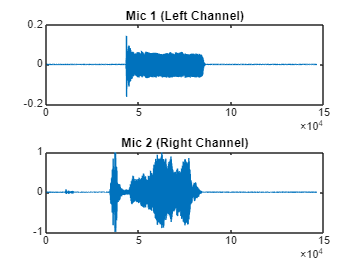

figure;
subplot(2,1,1); plot(mic1); title('Mic 1 (Left Channel)');
subplot(2,1,2); plot(mic2); title('Mic 2 (Right Channel)');

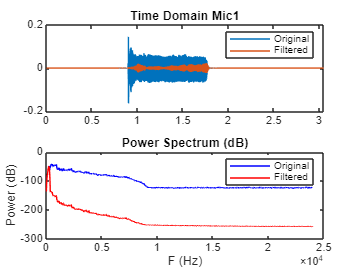

minLength = min(length(mic1), length(mic2));
mic1 = mic1(1:minLength);
mic2 = mic2(1:minLength);
t = (0:minLength-1) * (1/Fs);

% Lowpass
mic1_f = bandpass(mic1, [85 250], Fs);
mic2_f = bandpass(mic2, [85 250], Fs);

% Mic 1
figure; subplot(2,1,1);
plot(t, mic1); hold on; plot(t, mic1_f);
title('Time Domain Mic1'); legend('Original','Filtered');

subplot(2,1,2);
[po1,fo1] = pspectrum(mic1, Fs);
[pf1,ff1] = pspectrum(mic1_f, Fs);

plot(fo1, 10*log10(po1), 'b'); hold on; plot(ff1, 10*log10(pf1), 'r');
title('Power Spectrum (dB)'); xlabel('F (Hz)'); ylabel('Power (dB)'); legend('Original','Filtered');

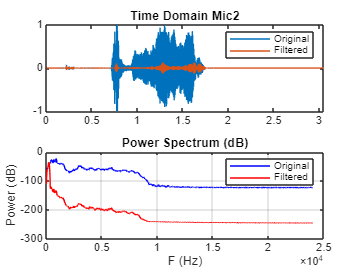


% Mic 2
figure; subplot(2,1,1);
plot(t, mic2); hold on; plot(t, mic2_f);
title('Time Domain Mic2'); legend('Original','Filtered');

subplot(2,1,2);
[po2,fo2] = pspectrum(mic2, Fs);
[pf2,ff2] = pspectrum(mic2_f, Fs);

plot(fo2, 10*log10(po2), '-b'); hold on; plot(ff2, 10*log10(pf2), '-r');
title('Power Spectrum (dB)'); xlabel('F (Hz)'); ylabel('Power (dB)'); legend('Original','Filtered');
grid on;

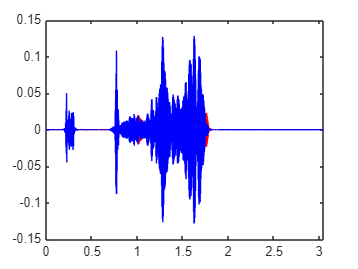


figure;
plot(t,mic1_f,"r")
hold on
plot(t,mic2_f,"b")
hold off

% TDOA
mic_spacing_m = 1.5; % Set your actual mic spacing in meters
v_sound = 343;     % m/s
max_delay_s = mic_spacing_m / v_sound;   % e.g. ~0.003 s
max_lag_samples = round(max_delay_s * Fs) ;  
% Normalized cross-correlation (GCC-style, time domain)
[xc12, lags12] = xcorr(mic1_f, mic2_f, max_lag_samples, 'normalized');
[~, idx12] = max(abs(xc12));
lag12       = lags12(idx12);
delay12     = lag12 / Fs;

fprintf('Lag:   %d samples\n', lag12);

Lag:   149 samples


fprintf('Delay: %.6f s  (%.4f ms)\n', delay12, delay12*1000);

Delay: 0.003104 s  (3.1042 ms)



v = 343; 
distance_mic = delay12 * v;
fprintf('Distance: %.3f\n',distance_mic);

Distance: 1.065


L = 0.5;